# The introduction figures

- map of RAFOS tracks for 100 days, with pair locations. 

- map of model tracks. 

- plot of pressure vs delta pressure over pair time. 

- time vs lat plot to show when exactly in time the floats were around. Includes a subplot with how number of pairs decreases as time progresses. 

- how do number of pairs decrease as time goes on.

clear all
close all 

% Load Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% Load models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, ...
        mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, ...
        depth(i)] = loadpairs(d(i));
    % delete the trajs in Scotia Sea
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03

% load topography
topo=load('../../data/topo2_SS_SO.mat');
topo.lon=topo.lon-360;
topo.bath=nanmoving_average2(topo.bath,4,2);
topo.bath(topo.bath<-7000)=-7000;
loni=topo.lon(1:5:end);
lati=topo.lat(1:2:end);
[X2 Y2] = meshgrid(loni,lati);
[X1 Y1] = meshgrid(topo.lon,topo.lat);
% change the topography to smoothed version (only for speed up of ploting
% as it is just a qualitative task)
bath = interp2(X1, Y1, topo.bath', X2, Y2,'cubic');
topo_intv=[-7000:500:0];

% load Orsi Fronts
pf= load('../../data/fronts/pf.txt');
saf = load('../../data/fronts/saf.txt');

% Pairs trajectories
% First just calculate for all possible pairs
sep_obs = calculate_seperation_timeseries(obs_traj);

%% Settings
plevel = [500 1000 1800]; % how large are the bins
ndays  = 100; % how long to track a pair
pdiff  = 200; % what is the p difference that we allow.

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end


clear mx my
npairs = zeros(ndays,2,2);
mpres = NaN*zeros(200,2,2); % just choose 200 to be greater than any number of pairs
mpresdiff = NaN*zeros(200,2,2);
mx = NaN*zeros(ndays,200,2,2);
time = NaN*zeros(ndays,200,2,2);
presgroups = cell(200,2,2); 

% my_ini 
for p = 1:length(plevel) -1 % loop over depth ranges
    for q = 1:length(distance_class) % loop over distance classes
        for i =1:length(obs_sep(p,q).sep) % loop over each pair
            for n =1:ndays % loop over the 100 days
                if ~isnan(obs_sep(p,q).sep(i).dist(n))
                    npairs(n,p,q) = npairs(n,p,q) + 1;
                end
            end
            mpres(i,p,q) = obs_sep(p,q).sep(i).meanpres;
            mpresdiff(i,p,q) = obs_sep(p,q).sep(i).meanpresdiff;
            
            mx(:,i,p,q) = 0.5*(obs_sep(p,q).sep(i).X1(1:ndays) + ...
                            obs_sep(p,q).sep(i).X2(1:ndays));
            time(:,i,p,q) = obs_sep(p,q).sep(i).time(1:ndays); 
            
            if (p==1 & q ==1)
                presgroups(i, p, q) = {'500-1000m, 10-15km'}; 
            elseif (p==1 & q==2)
                presgroups(i, p, q) = {'500-1000m, 30-35km'}; 
            elseif (p==2 & q==1)
                presgroups(i, p, q) = {'1000-1800m, 10-15km'}; 
            elseif (p==2 & q==2)
                presgroups(i, p, q) = {'1000-1800m, 30-35km'}; 
            end
        end
    end
end

gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

diff_pres_dist = 100; % this is half of the pressure difference allowed for the 
                      % relative disp pairs.

                      
for i = 1:length(plevel)-1
     npairs_dist_bins(:, i) = npairs_distbins(sep_obs, dist_bin, diff_pres_dist, plevel(i:i+1)); 
end

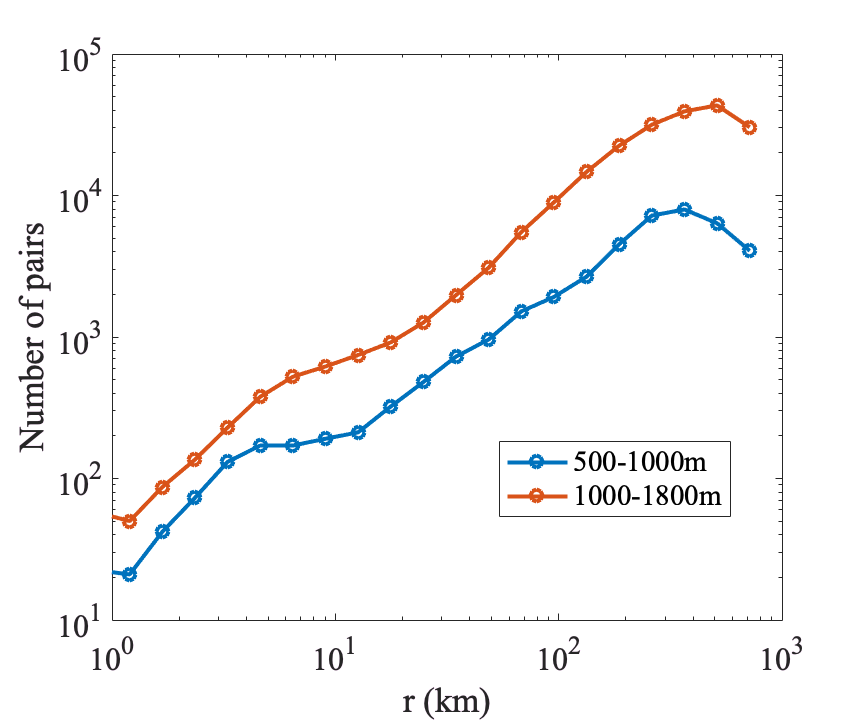

figure('unit','inches','pos',[0. 0. 6 5])
loglog(dist_axis/1e3, npairs_dist_bins, 'o-', 'linewidth',2)
legend('500-1000m', '1000-1800m', 'location','best')
xlim([1 1000])
xlabel('r (km)')
ylabel('Number of pairs')
set(gca, 'fontsize', 16, 'Fontname','Times')
print('num_pairs_dist.eps', '-depsc', '-painters')

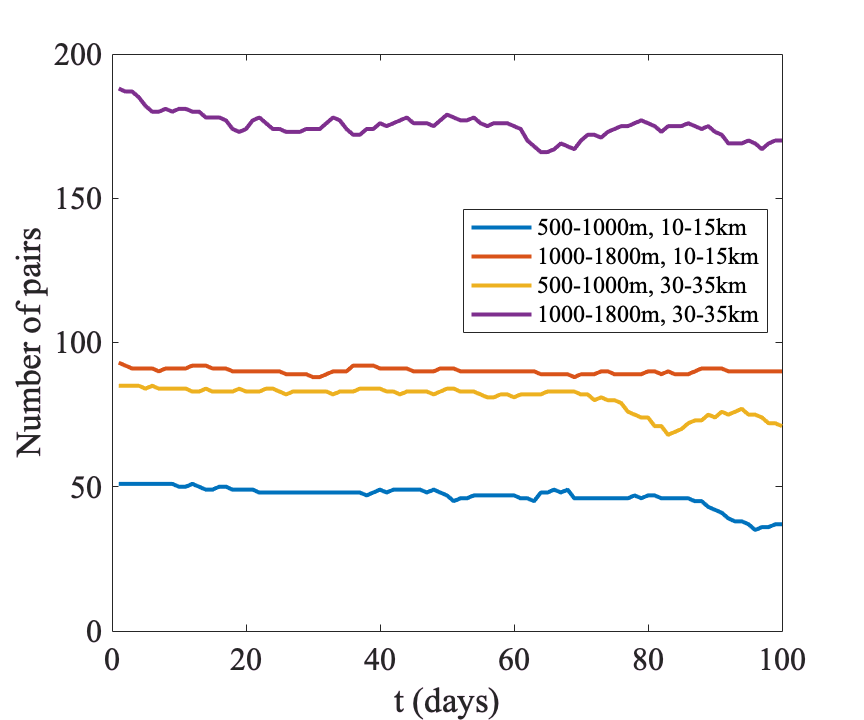


figure('unit','inches','pos',[0. 0. 6 5]),
hold all
for q = 1:length(distance_class) % loop over distance classes
    for p = 1:length(plevel) -1 % loop over depth ranges 
        plot(npairs(:,p,q), 'linewidth',2)
    end
end
xlabel('t (days)')
ylabel('Number of pairs')
ylim([0 200])
legend({'500-1000m, 10-15km', '1000-1800m, 10-15km', ...
    '500-1000m, 30-35km', '1000-1800m, 30-35km'}, 'location','best', 'fontsize',12) 
box on
set(gca, 'fontsize', 16, 'Fontname','Times')
print('num_pairs.eps', '-depsc', '-painters')

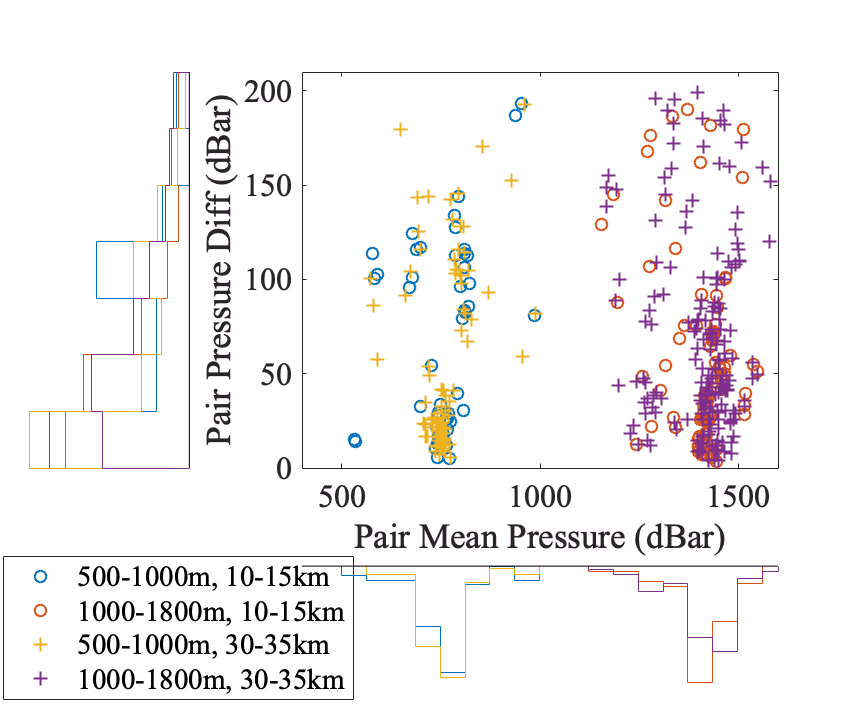

figure('unit','inches','pos',[0. 0. 6 5])
id = find(~isnan(mpres)); 
h = scatterhist(mpres(id), mpresdiff(id), 'Group', presgroups(id), ...%'Kernel','on', ...
    'Direction','out', 'Marker','oo++','LineWidth',2, ...
    'Linestyle', {'-','-','-','-'});
xlim([400 1600])
ylim([0, 210])
xlabel('Pair Mean Pressure (dBar)')
ylabel('Pair Pressure Diff (dBar)')
set(gca, 'fontsize', 16, 'Fontname','Times')
print('pres_arrangement.eps', '-depsc', '-painters')

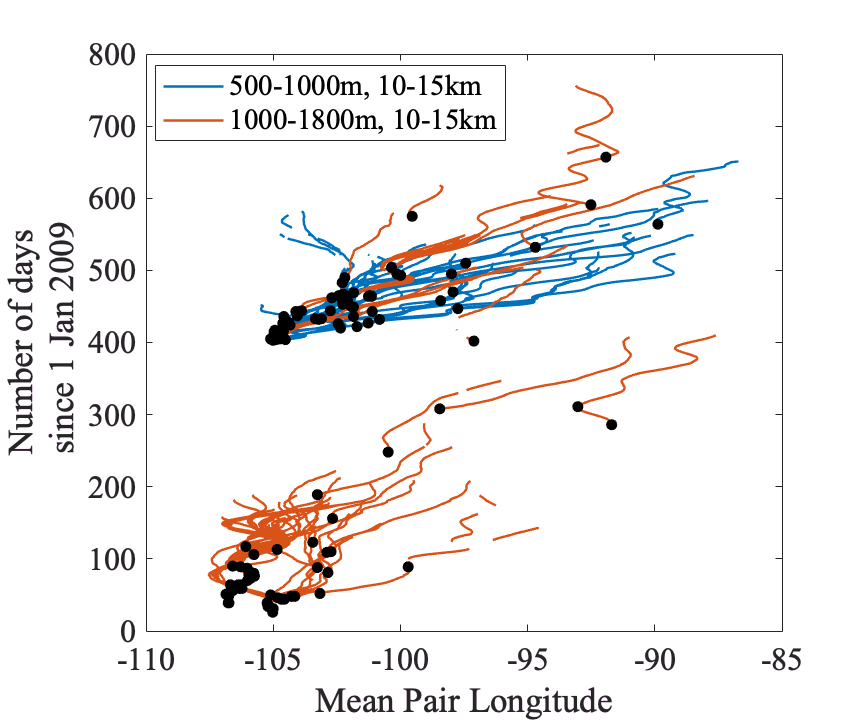

clear h
colors = lines(5); 
figure('unit','inches','pos',[0. 0. 6 5])
hold all
for p = 1:length(plevel) -1 % loop over depth ranges
    for q = 1 % loop over distance classes
        for i =1:length(obs_sep(p,q).sep) % loop over each pair
            h(p) = plot(mx(:,i, p,q), time(:,i, p,q)-14855+22, 'Color', colors(p,:), ...
            'linewidth',1.2);      
        end
    end
end

for p = 1:length(plevel) -1 % loop over depth ranges
    for q = 1 % loop over distance classes
        for i =1:length(obs_sep(p,q).sep) % loop over each pair
            ids = find(~isnan(mx(:,i, p,q)), 1); 
            plot(mx(ids,i, p,q), time(ids,i, p,q)-14855+22, ...
                '.', 'Markersize',15, 'Color', 'k')
        end
    end
end

box on
xlabel('Mean Pair Longitude')
ylabel({'Number of days'; ' since 1 Jan 2009'})
set(gca, 'fontsize', 16, 'Fontname','Times')
legend(h, {'500-1000m, 10-15km','1000-1800m, 10-15km'},'location','best')
print('time_lon.eps', '-depsc', '-painters')

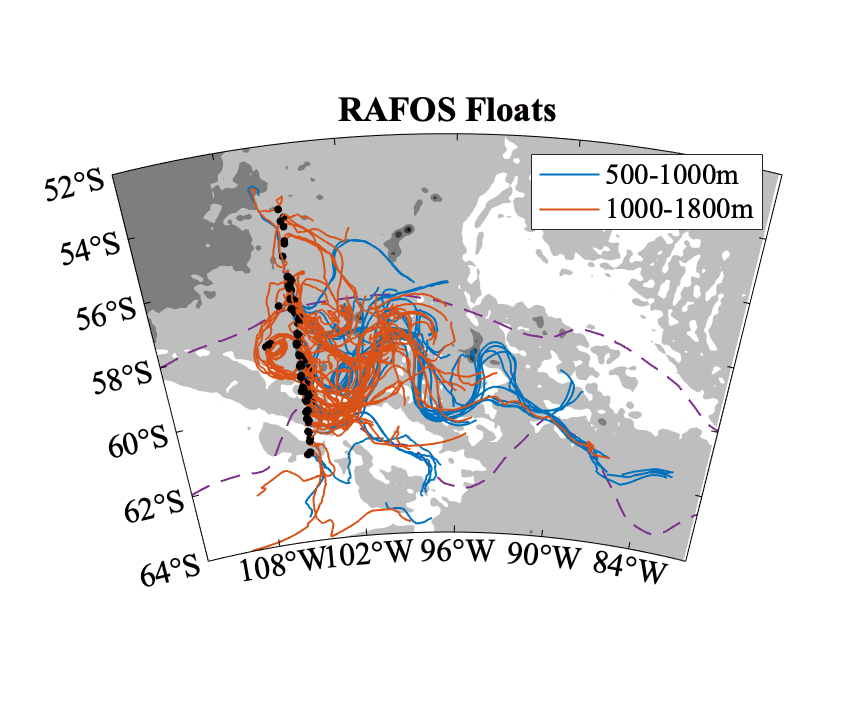

fh = figure('unit','inches','pos',[0. 0. 6 5]);

%set(fh, 'Visible','off');
clf
m_proj('Lambert','lat',[-64 -52], 'lon',[-113 -80]) ;
days_plt = 100; 
hold all 
col = colormap(1-gray(100));

colors = lines(5); 

%m_elev('contourf', [-6000 -4000 -2000],'edgecolor','none')

m_contourf(loni, lati, bath,[-6000 -5000 -4000  -3000 -2000], 'edgecolor','none');
%colorbar()

m_coast('patch',[0 0 0]);
m_plot(pf(:,1), pf(:,2),'--','linewidth',1,'color',colors(4,:));
m_plot(saf(:,1), saf(:,2),'--','linewidth',1,'color',colors(4,:));

for j=1:size(obs_traj.Xc, 2)
    ids = find(~isnan(obs_traj.Xc(:,j)),1);
    
    mp = nanmean(obs_traj.Pi( ids: ids+days_plt, j));
 
    if mp<1000
        p(1) = m_plot(obs_traj.Xc(ids: ids+days_plt, j), obs_traj.Yc(ids:ids+days_plt, j), ...
            'linewidth',1, 'color',colors(1,:));
    end
    
    m_plot(obs_traj.Xc(ids, j), obs_traj.Yc(ids, j), '.', 'Markersize',10,'color','k')
end 
for j=1:size(obs_traj.Xc, 2)
    ids = find(~isnan(obs_traj.Xc(:,j)),1);
    
    mp = nanmean(obs_traj.Pi( ids: ids+days_plt, j));
    
    if mp >= 1000
        p(2)= m_plot(obs_traj.Xc(ids: ids+days_plt, j), obs_traj.Yc(ids:ids+days_plt, j), ...
            'linewidth',1, 'color',colors(2,:));
    end
    
    m_plot(obs_traj.Xc(ids, j), obs_traj.Yc(ids, j), '.', 'Markersize',10,'color','k')
end 

set(gca, 'fontsize', 16, 'fontname','times')


m_grid('linest', 'none')
legend(p,{'500-1000m', '1000-1800m'}) 

title('RAFOS Floats')
%saveas(gca,'../figures/intro.eps')
print('rafos_floats.eps', '-depsc', '-painters')

%print(gcf, '-r0', 'intro.pdf');

## Model particles

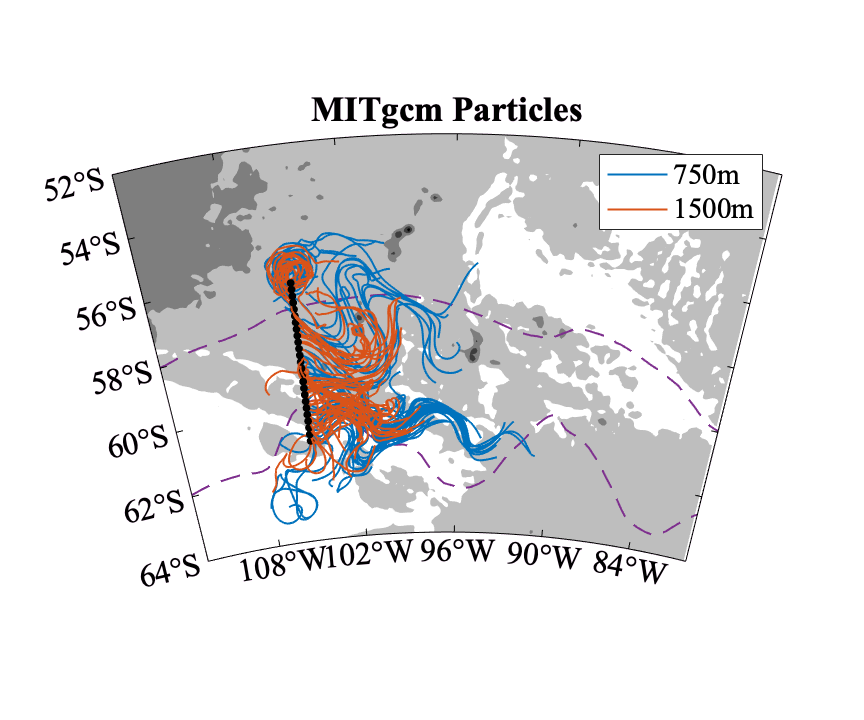

fh = figure('unit','inches','pos',[0. 0. 6 5]);


set(fh, 'Visible','off');
clf
m_proj('Lambert','lat',[-64 -52], 'lon',[-113 -80]) 
days_plt = 100; 
hold all 
col = colormap(1-gray(100));

colors = lines(5); 

%m_elev('contourf', [-6000 -4000 -2000],'edgecolor','none')

m_contourf(loni, lati, bath,[-6000 -5000 -4000  -3000 -2000], 'edgecolor','none');
%colorbar()

m_coast('patch',[0 0 0]);
m_plot(pf(:,1), pf(:,2),'--','linewidth',1,'color',colors(4,:));
m_plot(saf(:,1), saf(:,2),'--','linewidth',1,'color',colors(4,:));

for j=1:4:240
    ids = find(~isnan(mod_traj(1).X(:,j)),1);
    
    p(1) = m_plot(mod_traj(1).X(ids: ids+days_plt, j)-360, mod_traj(1).Y(ids:ids+days_plt, j), 'linewidth',1, 'color',colors(1,:));

    m_plot(mod_traj(1).X(ids, j)-360, mod_traj(1).Y(ids, j), '.', 'Markersize',10,'color','k');

end 

for j=1:4:240
    ids = find(~isnan(mod_traj(2).X(:,j)),1);
    p(2) = m_plot(mod_traj(2).X(ids: ids+days_plt, j)-360, mod_traj(2).Y(ids:ids+days_plt, j), 'linewidth',1, 'color',colors(2,:));

    m_plot(mod_traj(2).X(ids, j)-360, mod_traj(2).Y(ids, j), '.', 'Markersize',10,'color','k');

end 

set(gca, 'fontsize', 16,'fontname','times')
m_grid('linest', 'none')
legend(p,{'750m', '1500m'}) 

title('MITgcm Particles')
print('mitgcm_particles.eps', '-depsc', '-painters')
% saveas(gca,'../figures/intro_models.pdf')
